coef = 0.5; % unit distance between sensors divided by the wavelength of the signal

% input = [0 4 4]; % nested array
% input = [1 2 3]; % coprime array
% input = [2 4 3]; % super-nested array
% input = [3 4 4 3]; % augmented-nested array 1
input = [4 7 4]; % augmented-nested array 2

sensor_locations = Sensor_Locations(input)

sensor_locations =      1     2     4     6     8    16    24    32    33    35    37


sensor_placement = Sensor_Placement(sensor_locations)

sensor_placement =      1     1     0     1     0     1     0     1     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     1     1     0     1     0     1


diff_coarray = Diff_Coarray(sensor_placement)

diff_coarray =      1     1     1     2     1     4     1     3     1     2     1     1     1     1     1     1     1     1     1     1     2     1     1     1     1     1     1     1     3     1     1     2     3     2     5     2    11     2     5     2     3     2     1     1     3     1     1     1     1     1


uDOF = Uniform_Degrees_Of_Freedom(diff_coarray)

uDOF = 73

LuDOF = One_Side_Uniform_Degrees_Of_Freedom(diff_coarray)

LuDOF = 36

Now, let's use the calculated sensor_locations to compute the array pattern

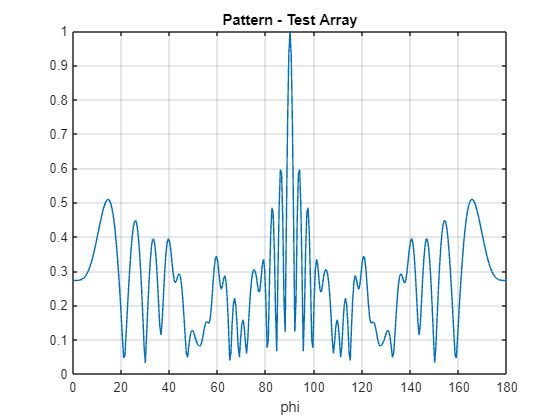

Array_Pattern(sensor_locations(end), sensor_locations, coef)

and solve an example DOA problem

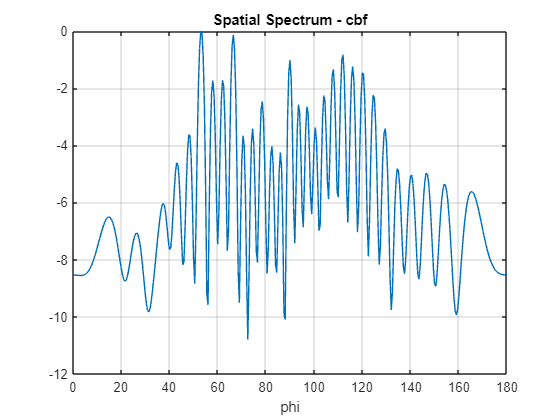

% doa = sort(randi(179, 1, 2));
% doa = [50 150];
doa = 90 - asind(0:0.2:0.6);
snapshots = 1000;
SNR_dB = 0;
mutual_coupling = true;
if mutual_coupling
    c0 = 1;
    c1 = 0.5 * exp(1i * 0.25 * pi);
    c2 = 0.5 * exp(1i * 0.7 * pi) / 2;
    c3 = 0.5 * exp(1i * 0.7 * pi) / 3;
    C = toeplitz([c0 c1 c2 c3 zeros(1, sensor_locations(end)-4)]);
else
    C = 1;
end
Spatial_Spectrum(sensor_locations(end), sensor_locations, doa, snapshots, SNR_dB, coef, "cbf", C);

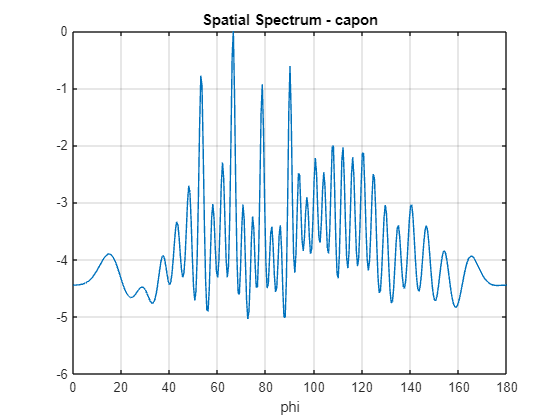

Spatial_Spectrum(sensor_locations(end), sensor_locations, doa, snapshots, SNR_dB, coef, "capon", C);

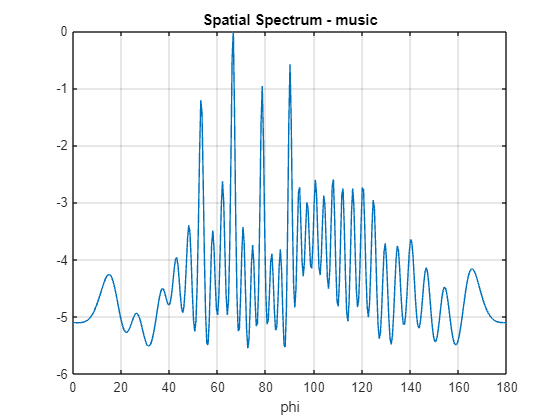

Spatial_Spectrum(sensor_locations(end), sensor_locations, doa, snapshots, SNR_dB, coef, "music", C);

### Functions Related To DOA Estimation

#### Array Pattern Computation

function Array_Pattern(M, sensor_locations, coef)
h_loc = Sensor_Placement(sensor_locations).';

angles = 0:0.5:180;
pattern = zeros(1, length(angles));
for i = 1:length(angles)
    h = h_loc .* exp(1i * 2 * pi * coef * (0:M-1).' * cosd(angles(i)));
    pattern(i) = abs(sum(h));
end
pattern = pattern / max(pattern);

figure;
plot(angles, pattern);
xlabel('phi'); xlim([0 180]);
title('Pattern - Test Array');
grid on;
end

#### Spatial Spectrum Computation

function spatial_spectrum = Spatial_Spectrum(M, sensor_locations, doa, N, SNR, coef, method, C)
n = length(doa);
h_loc = Sensor_Placement(sensor_locations).';

s = zeros(n, N);
theta = 180 * rand(n, 1);
for i = 1:n
    s(i, :) = exp(1i * 2 * pi * coef * (0:N-1) * cosd(theta(i)));
end
v = (1 / 10^(SNR/10)) * (1/sqrt(2)) * (randn(M, N) + 1i * randn(M, N));

A = zeros(M, n);
for i = 1:n
    A(:, i) = h_loc .* exp(1i * 2 * pi * coef * (0:M-1).' * cosd(doa(i)));
end

y = C * A * s + v;

angles = 0:0.5:180;
spatial_spectrum = zeros(1, length(angles));

if method == "cbf"
    for i = 1:length(angles)
        h = h_loc .* exp(1i * 2 * pi * coef * (0:M-1).' * cosd(angles(i)));
        spatial_spectrum(i) = abs(h' * (y * y') * h);
    end
else
    Ry = (1 / N) * (y * y');

    if method == "capon"
        for i = 1:length(angles)
            a_ = h_loc .* exp(1i * 2 * pi * coef * (0:M-1).' * cosd(angles(i)));
            h = ((eye(M)/(Ry)) * a_) / (a_' * (eye(M)/(Ry)) * a_);
            spatial_spectrum(i) = abs(h' * (y * y') * h);
        end

    else % method == "music"
        [eig_vecs, ~] = eig(Ry);    % eigen decomposition of the covariance matrix
        G = eig_vecs(:, 1:M-n);     % noise space
        
        for i = 1:length(angles)
            a_ = h_loc .* exp(1i * pi * (0:M-1).' * cos(angles(i) * pi / 180));
            spatial_spectrum(i) = 1/abs(a_' * (G * G') * a_);
        end
    end
end

spatial_spectrum = spatial_spectrum / max(spatial_spectrum);

figure;
plot(angles, 10 * log10(spatial_spectrum));
xlabel('phi'); xlim([0 180]);
title_str = 'Spatial Spectrum - ' + method;
title(title_str);
grid on;
end

#### Sensor Locations

function sensor_locations = Sensor_Locations(input)
if input(1) == 0 % nested array
    sensor_locations = Nested_Array_Locations(input(2:end));

elseif input(1) == 1 % coprime array
    sensor_locations = Coprime_Array_Locations(input(2), input(3));

elseif input(1) == 2 % super-nested array
    sensor_locations = Super_Nested_Array_Locations(input(2), input(3));
elseif input(1) == 3 % augmented-nested array 1
    sensor_locations = Augmented_Nested_Array_1_Locations(input(2), input(3), input(4));
elseif input(1) == 4 % augmented-nested array 2
    sensor_locations = Augmented_Nested_Array_2_Locations(input(2), input(3));
end
end

#### Nested Array Locations

function sensor_locations = Nested_Array_Locations(N)
K = length(N); % number of levels

sensor_locations = zeros(1, sum(N));
sensor_locations(1:N(1)) = 1:N(1);
for i = 2:K
    locations = 1:N(i);
    for j = 1:i-1
        for n = 1:N(i)
            locations(n) = locations(n) * (N(j) + 1);
        end
    end
    idx_init = sum(N(1:i-1))+1;
    idx_end = idx_init + N(i) - 1;
    sensor_locations(idx_init:idx_end) = locations;
end
end

#### Coprime Array Locations

function sensor_locations = Coprime_Array_Locations(M, N)
sensor_locations_1 = 1 + M * (0:N-1);
sensor_locations_2 = 1 + N * (0:2*M-1);

sensor_locations = sort([sensor_locations_1 sensor_locations_2(2:end)]);
end

#### Super-Nested Array Locations

function sensor_locations = Super_Nested_Array_Locations(N1, N2)
REM = rem(N1, 4);
r = floor(N1 / 4);
if REM == 0
    A1 = r; B1 = r - 1; A2 = r - 1; B2 = r - 2;
elseif REM == 1
    A1 = r; B1 = r - 1; A2 = r - 1; B2 = r - 1;
elseif REM == 2
    A1 = r + 1; B1 = r - 1; A2 = r; B2 = r - 2;
elseif REM == 3
    A1 = r; B1 = r; A2 = r; B2 = r - 1;
end
X1 = 1 + 2 * (0:A1);
Y1 = N1 + 1 - (1 + 2 * (0:B1));
X2 = (N1 + 1) + (2 + 2 * (0:A2));
Y2 = 2 * (N1 + 1) - (2 + 2 * (0:B2));
Z1 = (2:N2) * (N1 + 1);
Z2 = N2 * (N1 + 1) - 1;

sensor_locations = sort([X1 Y1 X2 Y2 Z1 Z2]);
end

#### Augmented Nested Array 1 Positions

function sensor_locations = Augmented_Nested_Array_1_Locations(N1, N2, L1)
if L1 == -1
    L1 = ceil(0.5 * (N1 + 1));
end
temp_locations = Nested_Array_Locations([N1 N2]); % parent nested array
temp_locations(N1 - L1 + 1:N1) = (N1 + 1) * N2 + temp_locations(N1 - L1 + 1:N1) - temp_locations(N1 - L1 + 1) + 1;
sensor_locations = sort(temp_locations);
end

#### Augmented Nested Array 2 Positions

function sensor_locations = Augmented_Nested_Array_2_Locations(N1, N2)
temp_locations = Nested_Array_Locations([N1 N2]); % parent nested array
temp_locations(3:2:N1) = (N1 + 1) * N2 - (rem(N1, 2) + 1) + temp_locations(3:2:N1);
sensor_locations = sort(temp_locations);
end

#### Sensor Placement

function sensor_placement = Sensor_Placement(sensor_locations)
sensor_placement = zeros(1, sensor_locations(end));
sensor_placement(sensor_locations) = 1;
end

#### Difference Coarray

function diff_coarray = Diff_Coarray(sensor_placement)
N = length(sensor_placement);
diff_coarray = zeros(1, 2 * N - 1);
for i = 1:N
    diff_coarray(N + i - 1) = sensor_placement(i:end) * sensor_placement(1:end-i+1).';
end
diff_coarray(1:N-1) = diff_coarray(end:-1:N+1);
end

#### Degrees of Freedom

function degrees_of_freedom = Degrees_Of_Freedom(N)
K = length(N); % number of levels
degrees_of_freedom = 2 * (([0 N] * [N 0].') + N(K) - 1) + 1;
end

#### Uniform Degrees of Freedom

function uniform_degrees_of_freedom = Uniform_Degrees_Of_Freedom(diff_coarray)
uniform_degrees_of_freedom = 0;
length_diff_coarray = length(diff_coarray);
for i = (length_diff_coarray + 1)/2:length_diff_coarray
    if diff_coarray(i) == 0
        break
    end
    uniform_degrees_of_freedom = uniform_degrees_of_freedom + 1;
end
uniform_degrees_of_freedom = 2 * uniform_degrees_of_freedom - 1;
end

#### One-Side Uniform Degrees of Freedom

function one_side_uniform_degrees_of_freedom = One_Side_Uniform_Degrees_Of_Freedom(diff_coarray)
uniform_degrees_of_freedom = Uniform_Degrees_Of_Freedom(diff_coarray);
one_side_uniform_degrees_of_freedom = 0.5 * (uniform_degrees_of_freedom - 1);
end